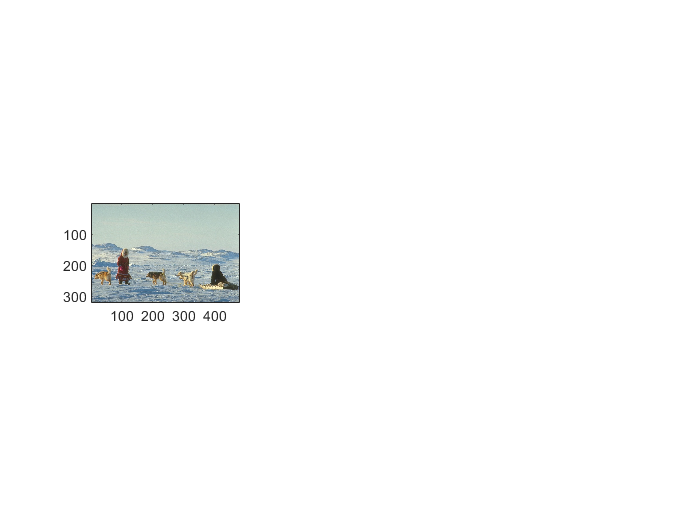

img = imread('./images/310007.jpg');
subplot(1,3,1); imagesc(img); axis image;

[X,L] = getfeatures(img, 7);
XX = [X(1:2,:); X(3:4,:)/10];

k=10;

[d,n] = size(XX);

init_miu = XX(:,randperm(n, k));

init_pi = zeros(1,k); 
init_sigma = zeros(d,d,k); 
 
a=repmat(sum(XX'.*XX',2),1,k);
b=repmat(sum(init_miu'.*init_miu',2)',n,1);
c=2*XX'* init_miu;
distance = a + b - c;

[~,labels] = min(distance,[],2);

for j=1:k
    Xj = XX(:,labels == j);
    init_pi(j) = size(Xj,1) / n;
    cc = cov(Xj');
    init_sigma(:,:,j) = cc;
end
    
Y = EM(XX, k, init_miu,init_sigma,init_pi);

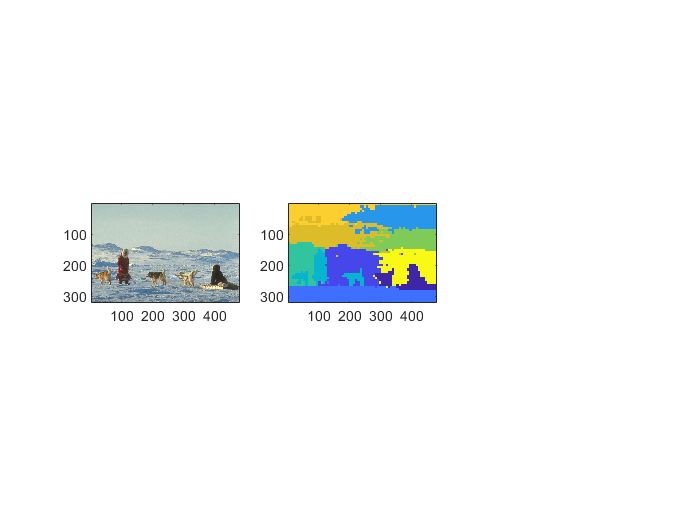

segm = labels2segm(Y,L);
subplot(1,3,2); imagesc(segm); axis image;

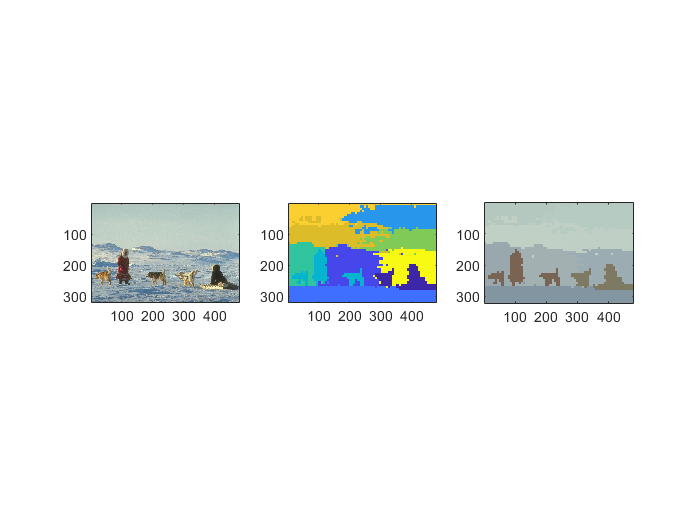

csegm = colorsegm(segm,img);
subplot(1,3,3); imagesc(csegm); axis image

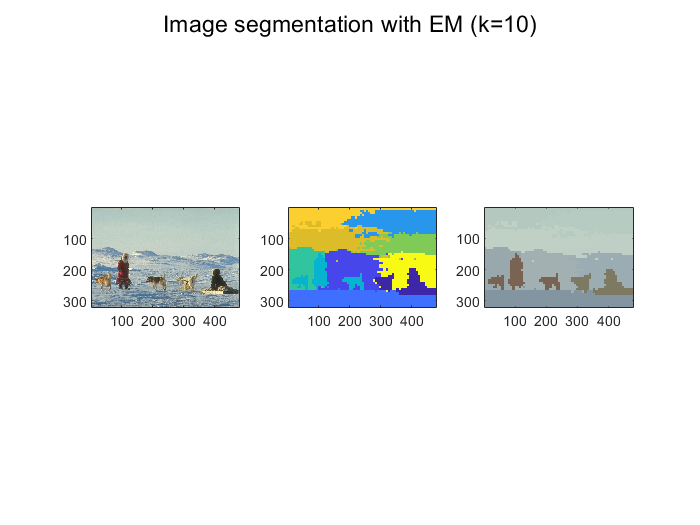

sgtitle('Image segmentation with EM (k=10)');